# Initial investigation of Sophia Alme's second data set

*John Nagy*

*July 2023*

## Summary of experimental design

Here we study the effects of N and P on the population dynamics of *Tribolium confusum*. Populations are cultured in small plastic cups with 25 grams of standard culture media (mixture of unbleached flour with 5% yeast by mass) to which varying amounts of sodium nitrate (NaNO$_3$) and monopotassium phosphate (KH$_2$PO$_4$) have been added. Initial populations in each cup included 20 fully adult beetles obtained from a random sample of our stock laboratory cultures.

    We use a 2-factor, not quite fully crossed, slightly unbalanced design (Fig. 1). Factor 1 is the amount of phosphorus (P) added in the form of KH$_2$PO$_4$, in percent by mass. Factor 2 is the same for added nitrogen (N) as NaNO$_3$. Beetles are censused in each cup every 2 weeks.

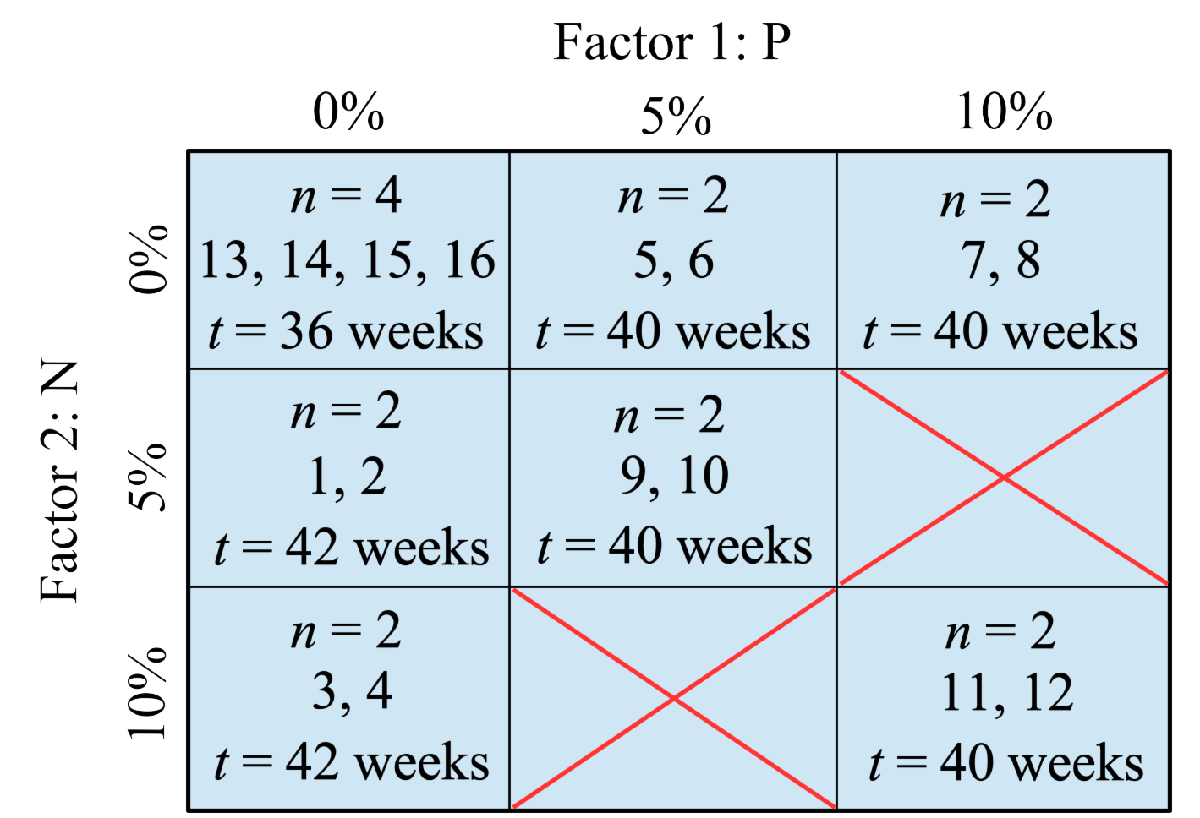

**Figure 1. **Design of the *Tribolium* N and P experiment. Factors 1 and 2 are the amounts of N and P added to the media in each culture tube, in percent by mass. Each cell shows the number of cups ($n$, top line) in each treatment, cup ID numbers (middle line), and time in study as of July 4, 2023.

## Sophia's new data

As of this writing, Sophia has completed counts up through July 2, 2023. I've saved the data as a `.mat` file, which I load here. (To run this LiveScript, you'll need to make sure the data file is in the same directory or add the path to the following line.)

load("TData.mat");
TData

TData = 328×13 table
      Date      TimeStep    Cup     CupID     Larvae    Pupae    Adult    Callows    Dead    Trial    Incub    N     P 
    ________    ________    ___    _______    ______    _____    _____    _______    ____    _____    _____    __    __

    09/25/22       1         1     T1 N5         0        0       20         0        0        1        A       5     0
    09/25/22       1         2     T2 N5         0        0       20         0        0        2        B       5     0
    09/25/22       1         3     T1 N10        0      

As a first pass, I'll plot everything lumped together; that is, each point represents all cups at that given time step averaged together, regardless of treatment. We already know that N, at least, appears to have a significant effect on the dynamics, so this plot should be taken with a large grain of salt.

To be clear, time step 1 in the data set is the first measurement. At time step 0, there were always 20 adults. 

% Initialize time and set up the table of means for each age class

n = 0:max(TData.TimeStep);
Week = n*2;  % Convert to weeks

Means = table; % Preallocation of table of means for each age class

Means.Larvae = zeros(max(n)+1,1);
Means.Pupae = zeros(max(n)+1,1);
Means.Adult = zeros(max(n)+1,1);
Means.Adult(1) = 20;

This next part is a little tricky because the cups were started at different times and therefore have different maximal time steps. At this time measurement, they fall into 3 natural groups:

- Cups 13-16; 36 weeks;

- Cups 5-12; 40 weeks;

- Cups 1-4; 42 weeks. 

Now calculate means for each time block.

for i = n(2:max(n)+1)
    Means.Larvae(i+1) = mean(TData.Larvae(TData.TimeStep == i), "omitnan");
    Means.Pupae(i+1) = mean(TData.Pupae(TData.TimeStep == i), "omitnan"); 
    Means.Adult(i+1) = mean(TData.Adult(TData.TimeStep == i), "omitnan");
end

Means

Means = 22×3 table
    Larvae    Pupae     Adult 
    ______    ______    ______

         0         0        20
         0         0    19.312
       187         0        19
    427.81    170.25    53.625
    134.88    113.75    423.81
    57.875    31.438    482.38
    100.12    9.5625    408.88
    133.25    12.125    338.75
     72.25    16.062    293.19
    42.438    13.125    246.56
    148.81     6.125     218.5
    164.12     10.25    203.69
    108.81    11.312    188.69
        58    10.375     167.5
    140.38    7.0625    151.06
    97.375    4.3125    124.75


Now standard deviations:

sd = table;  % Preallocation of the table of standard deviations

sd.Larvae = zeros(max(n)+1,1);
sd.Pupae = zeros(max(n)+1,1);
sd.Adult = zeros(max(n)+1,1);

for i = n(2:max(n)+1)
    sd.Larvae(i+1) = std(TData.Larvae(TData.TimeStep == i), "omitnan");
    sd.Pupae(i+1) = std(TData.Pupae(TData.TimeStep == i), "omitnan"); 
    sd.Adult(i+1) = std(TData.Adult(TData.TimeStep == i), "omitnan");
end

sd

sd = 22×3 table
    Larvae    Pupae     Adult 
    ______    ______    ______

         0         0         0
         0         0    1.0145
    101.25         0    1.0954
    140.93    76.285    71.442
    65.822    52.633    107.22
    29.017    15.979    97.177
    46.295    4.7605    98.566
    65.222    10.664     125.8
    31.531    20.075    143.23
    21.945    16.883    99.208
    84.771    6.0319    98.318
    92.622    14.626    73.945
     73.54    16.173    62.801
    26.306    18.388    73.102
    101.37    7.7929    65.634
    77.778    5.2627    53.754


Finally, 95% confidence intervals. We have the 3 sets that will require different values for $t^*$, for the Student's $t$ distribution:

- Time steps 0-18: $n = 16$, $t^* = 2.131$;

- Time steps 19-20: $n = 12$, $t^* = 2.201$;

- Time step 21: $n=4$; $t^* = 2.776$.

CI = table; % Preallocation and, below, calculation of confidence interval half-widths

CI.Larvae = zeros(max(n)+1, 1);
CI.Pupae = zeros(max(n)+1, 1);
CI.Adult = zeros(max(n)+1, 1);

n1 = 16;
n2 = 12;
n3 = 4;

t1 = 2.131;
t2 = 2.201;
t3 = 2.776;

TSet1 = (n > 0) & (n < 19);
TSet2 = (n > 18) & (n < 21);

% Time block 1
CI.Larvae(find(TSet1)) = (t1*sd.Larvae(TSet1))/sqrt(n1);
CI.Pupae(find(TSet1)) = (t1*sd.Pupae(TSet1))/sqrt(n1);
CI.Adult(find(TSet1)) = (t1*sd.Adult(TSet1))/sqrt(n1);

% Time block 2
CI.Larvae(find(TSet2)) = (t2*sd.Larvae(TSet2))/sqrt(n2);
CI.Pupae(find(TSet2)) = (t2*sd.Pupae(TSet2))/sqrt(n2);
CI.Adult(find(TSet2)) = (t2*sd.Adult(TSet2))/sqrt(n2);

%Time block 3
CI.Larvae(22) = (t3*sd.Larvae(22))/sqrt(n3);
CI.Pupae(22) = (t3*sd.Pupae(22))/sqrt(n3);
CI.Adult(22) = (t3*sd.Adult(22))/sqrt(n3);

CI

CI = 22×3 table
    Larvae    Pupae      Adult 
    ______    ______    _______

         0         0          0
         0         0    0.54046
    53.942         0     0.5836
     75.08    40.641     38.061
    35.067     28.04     57.124
    15.459    8.5128     51.771
    24.663    2.5362     52.511
    34.747    5.6811     67.019
    16.798    10.695     76.306
    11.691    8.9946     52.853
    45.162    3.2135     52.379
    49.345    7.7922     39.394
    39.179    8.6161     33.457
    14.014    9.7962     38.945
    54.004    4.1517     34.966
    41.436    2.8037     28.638


## Plots

### Data

The first figure is a plot of Sophia's data. Again, I'm not really analyzing these data. I'm just trying to compare the data with the model solution to see what, if any, qualitative agreement there might be. 

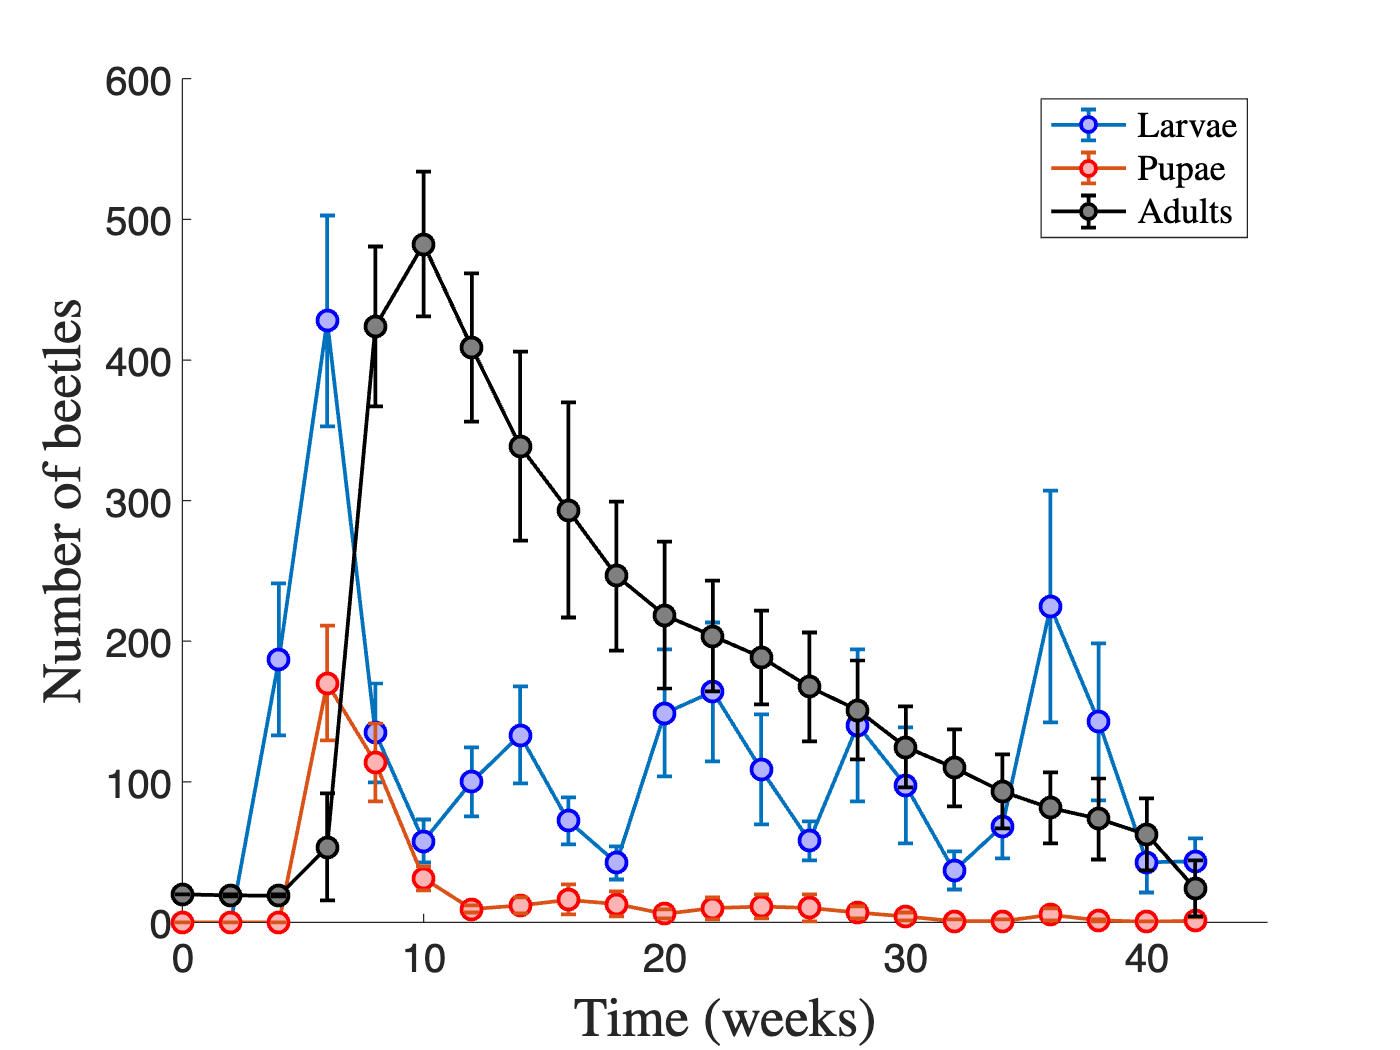

figure
hold on

errorbar(Week, Means.Larvae, CI.Larvae, ...
         '-o', 'MarkerSize', 8, ...
         'MarkerEdgeColor', 'b',...
         'MarkerFaceColor', [0.7 0.7 1], ...
         'LineWidth', 1.5)
errorbar(Week, Means.Pupae, CI.Pupae, ...
         '-o', 'MarkerSize', 8, ...
         'MarkerEdgeColor', 'r',...
         'MarkerFaceColor', [1 0.7 0.7], ...
         'LineWidth', 1.5)
errorbar(Week, Means.Adult, CI.Adult, ...
         '-o', 'MarkerSize', 8, ...
         'MarkerEdgeColor', 'k',...
         'MarkerFaceColor', [0.5 0.5 0.5], ...
         'Color', 'k', ...
         'LineWidth', 1.5)

ax = gca;
ax.FontSize = 16;
ax.YLim = [0, 600];
ax.XLim = [0, 45];

xlabel('Time (weeks)', ...
       'Interpreter', 'latex', ...
       'FontSize', 22)

ylabel('Number of beetles', ...
       'Interpreter', 'latex', ...
       'FontSize', 22)

lgnd = legend('Larvae', 'Pupae', 'Adults');
lgnd.Interpreter = 'latex';
lgnd.Location = 'northeast';

### Plots of total numbers and biomass

Here I look at the dynamics of total biomass over time. A crude way to do that is simply to plot the total numbers of distinct organisms, which I'll do here.

First, I construct a data frame that includes time step, total number of beetles in any life stage and total biomass. Park (1934) reports among many other things the mass of various larval instars as well as mass of adults. Assuming an equal number of beetles of each instar (which is dubious, but the larger instars bias the weight immensely, and they would be the smallest class), the mean mass of a larva is 0.6673 mg and the mean mass of an adult is 1.63 mg. I'll assume that pupae are the same mass as adults. In the data frame, I'll convert mg to g.

Total = table;

Total.n = TData.TimeStep;
Total.Critters = TData.Larvae + TData.Pupae + TData.Adult;
Total.Biomass = (0.6673*TData.Larvae + 1.63*(TData.Adult + TData.Pupae))/1000;

Total

Total = 328×3 table
    n    Critters    Biomass 
    _    ________    ________

    1       20         0.0326
    1       20         0.0326
    1       20         0.0326
    1       20         0.0326
    1       20         0.0326
    1       19        0.03097
    1       18        0.02934
    1       20         0.0326
    1       17        0.02771
    1       20         0.0326
    1       20         0.0326
    1       18        0.02934
    2      161        0.12573
    2      185        0.14174
    2       97       0.083982
    2      155        0.12172


Next I calculate the summary statistics on the total number of beetles.

TotalStats = table;

TotalStats.Means = zeros(length(n),1);
TotalStats.sd = zeros(length(n),1);
TotalStats.CI = zeros(length(n),1);

for i = n+1
    TotalStats.Means(i) = mean(Total.Critters(Total.n == i-1));
    TotalStats.sd(i) = std(Total.Critters(Total.n == i-1));
    TotalStats.CI(i) = 2.201*TotalStats.sd(i)/sqrt(12);
end

TotalStats

TotalStats = 22×3 table
    Means       sd        CI   
    ______    ______    _______

       NaN       NaN        NaN
    19.312    1.0145    0.64457
       206    101.46     64.467
    651.69    164.49     104.51
    672.44    140.95     89.555
    571.69    108.18     68.735
    518.56    113.28     71.976
    484.12    126.88     80.617
     381.5    135.45     86.061
    302.12    100.11     63.607
    373.44    108.54     68.965
    378.06    127.54     81.034
    308.81    116.97     74.317
    235.88     81.47     51.764
     298.5    97.917     62.214
    226.44    81.229     51.611


Next I do the same for total biomass.

TotalBiomass = table;

TotalBiomass.Means = zeros(max(Week),1);
TotalBiomass.sd = zeros(max(Week),1);
TotalBiomass.CI = zeros(max(Week),1);

for i = n+1
    TotalBiomass.Means(i) = mean(Total.Biomass(Total.n == i));
    TotalBiomass.sd(i) = std(Total.Biomass(Total.n == i));
    TotalBiomass.CI(i) = 2.201*TotalBiomass.sd(i)/sqrt(12);
end

TotalBiomass

TotalBiomass = 42×3 table
     Means         sd           CI    
    ________    _________    _________

    0.031479    0.0016536    0.0010507
     0.15576     0.067923     0.043157
      0.6504      0.21516      0.13671
     0.96623      0.19329      0.12281
     0.87613      0.16747       0.1064
     0.74887      0.16649      0.10578
     0.66084       0.1982      0.12593
     0.55229      0.22383      0.14222
     0.45161      0.16335      0.10379
     0.46544      0.15192     0.096523
     0.45824      0.14234     0.090436
     0.39861      0.13607     0.086455
     0.32864      0.13159     0.083607
     0.35142      0.10382     0.065961
     0.27535     0.088355     0.056138
     0.20545     0.087796     0.055783


Now, plot total numbers of critters.

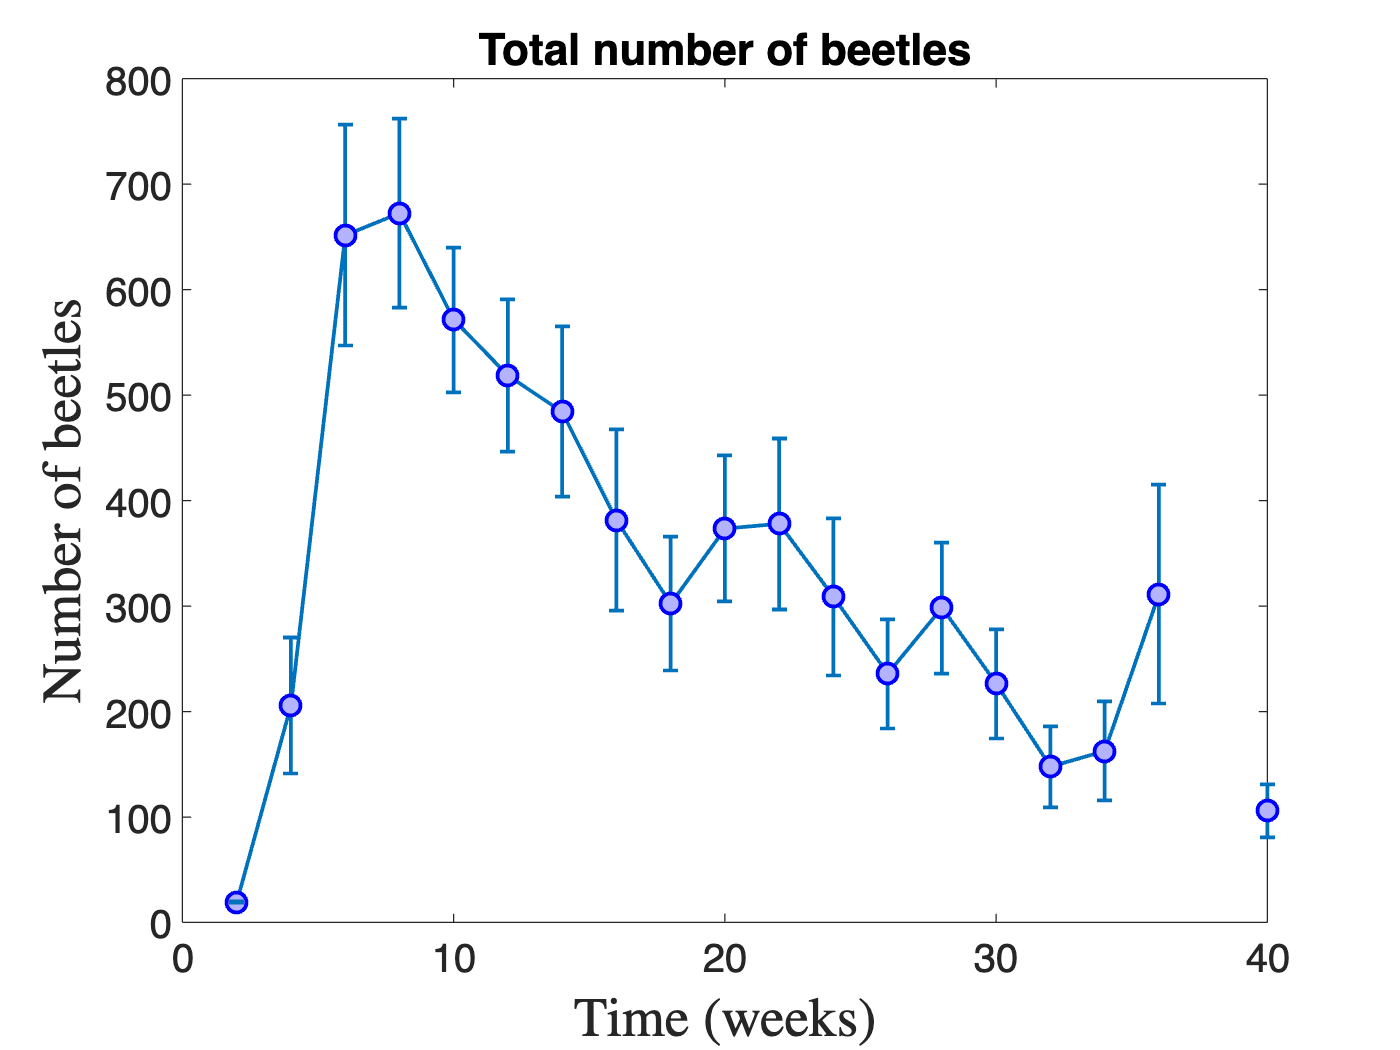

figure

errorbar(Week, TotalStats.Means, TotalStats.CI, '-o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b',...
    'MarkerFaceColor', [0.7 0.7 1], 'LineWidth', 1.5)

ax = gca;
ax.FontSize = 16;

xlabel('Time (weeks)', 'Interpreter', 'latex', 'FontSize', 22)
ylabel('Number of beetles', 'Interpreter', 'latex', 'FontSize', 22)
title('Total number of beetles')

And now total biomass in critters.

% figure
% 
% errorbar(Week, TotalBiomass.Means, TotalBiomass.CI, '-o', 'MarkerSize', 8, 'MarkerEdgeColor', 'b',...
%     'MarkerFaceColor', [0.7 0.7 1], 'LineWidth', 1.5)
% 
% ax = gca;
% ax.FontSize = 16;
% 
% xlabel('Time (weeks)', 'Interpreter', 'latex', 'FontSize', 22)
% ylabel('Biomass of beetles', 'Interpreter', 'latex', 'FontSize', 22)
% title('Beetle biomass')

